load FlightData\Standard_LinY.mat
SoftKite_TL

## Estimation of Efficiencty

C_L = Cl.signals.values; % Different from TL
C_D = Cd.signals.values; % Different from TL
r_l = vecnorm(pos')'; % equivalent to states.signals.values(:,5)
beta = alpha.signals.values - alpha_0;
C_Deq = C_D.*(1 + (n_line*r_l*parameters.d_l*parameters.Cd_l.*cos(beta))./(4*parameters.A*C_D))

C_Deq =     0.1955
    0.1955
    0.1955
    0.1955
    0.1955
    0.1228
    0.0887
    0.0883
    0.1063
    0.1397


Seems correct, C_Deq is higher bc there is cable drag involved.

The introduction of beta gives minimal difference, the difference is 2 orders of magnitude less than the absolute value 

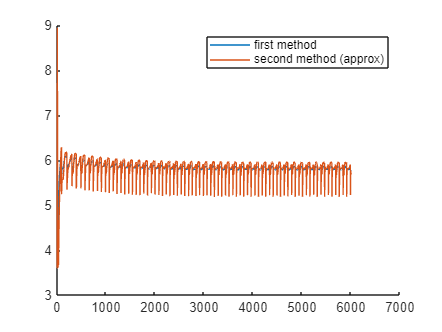

E_eq_1 = C_L./C_Deq;
E_eq_2 = cos(beta)./sin(beta);
figure, hold on;
plot(E_eq_1), plot(E_eq_2)
legend('first method','second method (approx)'), hold off

They match up pretty well, we can decide to pick any of the two to compute efficiency, maybe first method is less prone to incorrect assumptions

## Computation of W_er_norm

E_eq = E_eq_1;

First approach 

C = 0.5*parameters.rho*parameters.A*C_L.*E_eq.^2.*(1+1./E_eq.^2).^(3/2);
W_er_norm_1 = sqrt(F_T_norm./C);

Second approach 

% for Vkite we can use the one from simulation (Vkite) or vecnorm(posDot')', they
% are the same 
W_er_norm_2 = vecnorm(posDot')'./E_eq;

Comparison

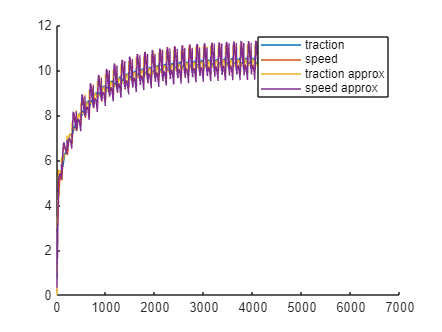

figure, hold on

% case with the other computation of efficiency
E_eq = E_eq_2;
C = 0.5*parameters.rho*parameters.A*C_L.*E_eq.^2.*(1+1./E_eq.^2).^(3/2);
W_er_norm_3 = sqrt(F_T_norm./C);
W_er_norm_4 = vecnorm(posDot')'./E_eq;
plot(W_er_norm_1), plot(W_er_norm_2)
plot(W_er_norm_3), plot(W_er_norm_4)

legend('traction', 'speed', 'traction approx', 'speed approx')

## Absolute Wind Recovery

W_er_norm = W_er_norm_1;
L_dot = statesdot.signals.values(:,5); % unwinding/winding speed
l = pos./(vecnorm(pos')'); % kite position versor

The first approach can be to take 3 measurement at the time, assuming that the wind doesn't change during the measurement and solve system of 3 eq in 3 unknowns

tol = 1e-12;
maxIter = 20;
blockSize = 50;
initStep = 2;
maxStep = 6001; % Shouldn't exceed size(l)

iSequence = initStep:blockSize:maxStep-initStep;
A = zeros(blockSize,3);
B = zeros(blockSize,1);
W_est = zeros(floor((maxStep)/blockSize),3);
for i = iSequence
    for j = 1:blockSize
        A(j,:) = l(i+j-1,:); 
        B(j) = W_er_norm(i+j-1)+L_dot(i+j-1);
    end
    W_est((i-initStep+blockSize)/blockSize,:) = lsqr(A,B,tol,maxIter,[],[], W(i,:)')';
end

lsqr converged at iteration 4 to a solution with relative residual 0.15.
lsqr converged at iteration 4 to a solution with relative residual 0.044.
lsqr converged at iteration 4 to a solution with relative residual 0.024.
lsqr converged at iteration 4 to a solution with relative residual 0.011.
lsqr converged at iteration 4 to a solution with relative residual 0.031.
lsqr converged at iteration 4 to a solution with relative residual 0.0093.
lsqr converged at iteration 4 to a solution with relative residual 0.032.
lsqr converged at iteration 4 to a solution with relative residual 0.025.
lsqr converged at iteration 4 to a solution with relative residual 0.0091.
lsqr converged at iteration 4 to a solution with relative residual 0.033.
lsqr converged at iteration 4 to a solution with relative residual 0.011.
lsqr converged at iteration 4 to a solution with relative residual 0.04.
lsqr converged at iteration 5 to a solution with relative residual 0.0017.
lsqr converged at iteration 4 to a so

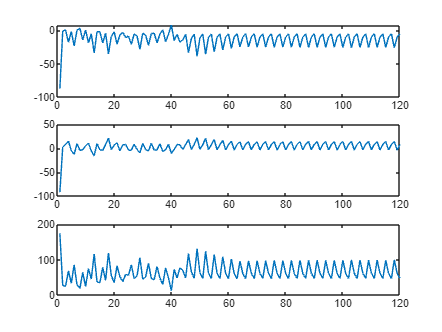


W_est_full = reshape(repmat(W_est, 1, 1, blockSize), [], 3);

figure
subplot(3,1,1)
plot(W_est(:,1));
subplot(3,1,2)
plot(W_est(:,2));
subplot(3,1,3)
plot(W_est(:,3));

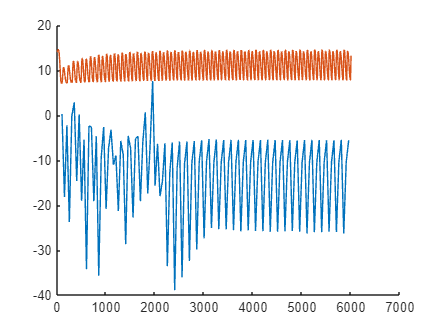


N_filter = 100; % Steps to skip in the comparison (100 steps = 1s)

iFilterStart = 1+floor(N_filter/blockSize);
iSequence = iSequence(1,iFilterStart:end);
figure, hold on
plot(iSequence,W_est(iFilterStart:end,1));
plot(W(:,1))

abs(norm(W_est(iFilterStart:end,1) - W(iSequence,1)))

ans = 288.0612

abs(norm(W_est_full(N_filter:5998,1)-W(N_filter:5998,1)))

ans = 3.0090e+03